%Limpiamos en caso de que haya otro robot cargado
clear ur

%Conectamos nuevamente con el cobot
ur = urRTDEClient('192.168.1.10','CobotName','universalUR5e') %Conectamos ROS de matlab con el cobot

ur =   urRTDEClient with properties:

            CobotName: 'universalUR5e'
       URControllerIP: '192.168.1.10'
    ControllerVersion: '5.11.10.0'
        RTDEFrequency: 125
    ConnectionTimeOut: 10
        RigidBodyTree: [1×1 rigidBodyTree]


jointAngles = readJointConfiguration(ur) %Lee los angulos del brazo

jointAngles =     1.3780   -1.6747    1.8181   -1.8034   -1.6673   -2.8901



% Ruta de la carpeta donde se guardará la imagen
    folderPath = 'C:\Users\hecto\Documents\0_ACTIVIDADES Y CURSOS\ROBOCUP_VW\CAMARA\COBOTPOSES';
    % Verificar si la carpeta existe
    if ~exist(folderPath, 'dir')
        mkdir(folderPath);  % Crear la carpeta si no existe
    end
    
% Crear una tabla vacía con las etiquetas especificadas
columnas = {'base', 'hombro', 'codo', 'w1', 'w2', 'w3'};
% Crear una tabla con tipos de datos predefinidos
TablaDatos = table([], [], [], [], [], [],'VariableNames', columnas);
i = 01;

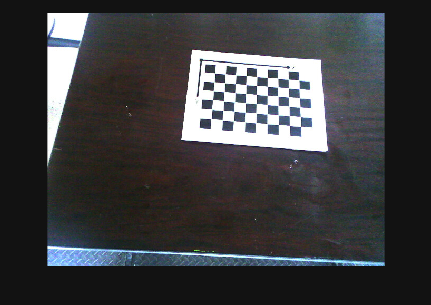

%Verificador de fotos 
[imgdata,img] = fotosw();
imshow(img);

%Guardador de pose en tabla y fotos en carpeta
 
%Leemos los valores de la pose
pose = rad2deg(readJointConfiguration(ur))

pose =    89.0660 -118.8981   95.7742  -61.9064  -92.4264 -183.4138



%Almacenamos los valores dentro de las varibles que guardaran los objetos en la tabla
base = pose(1); hombro = pose(2); codo = pose(3);
w1 = pose(4); w2 = pose(5); w3 = pose(6);

%Almacenamos los valores ahora si en la tabla y generamos una nueva fila
nueva_fila = {base,hombro,codo,w1,w2,w3};
TablaDatos = [TablaDatos; nueva_fila];

%Guardamos la tabla
save('jntconfig.mat','TablaDatos');

%Guardamos la imagen en la carpeta
% Nombre del archivo
fileName = sprintf('%d.png', i);
% Ruta completa del archivo
fullPath = fullfile(folderPath, fileName);
imwrite(imgdata, fullPath);
i = i + 01;